syms w t

d1 = 40.025/100; %m
d2 = 18.28/100; %m

A = -0.027;
phi = pi/2;

r = A*(3+cos((3*w*t)+phi));

x = r*cos(w*t) + 0.2;
y = r*sin(w*t) + 0.4;

v_x = diff(x,t);
v_y = diff(y,t);

v = sqrt(v_x^2+v_y^2);

a_x = diff(v_x,t);
a_y = diff(v_y,t);

theta_2 = -acos((x^2+y^2-d1^2-d2^2)/(2*d1*L2));
omega_2 = diff(theta_2,t);
alpha_2 = diff(omega_2,t);

theta_1 = atan(y/x) - atan(d2*sin(theta_2)/(d1+d2*cos(theta_2)));
omega_1 = diff(theta_1,t);
alpha_1 = diff(omega_1,t);

## Asignación de w y t

theta = 2*pi;
T = 16;
t = linspace(0,T,100);
w = theta/T;
v_min = 0.01; %m/s
v_max = 0.1; %m/s
w = mean([v_min,v_max])/mean(eval(r));

## Posición de HOME

x_home = 0.09; %m
y_home = 0.2072; %m
h_home = sqrt(d1^2-(x_home/2)^2);

theta_2_home = -acos((x_home^2+y_home^2-d1^2-d2^2)/(2*d1*d2));
theta_1_home = atan(y_home/x_home) - atan(d2*sin(theta_2_home)/(d1+d2*cos(theta_2_home)));

## Gráficas

## x

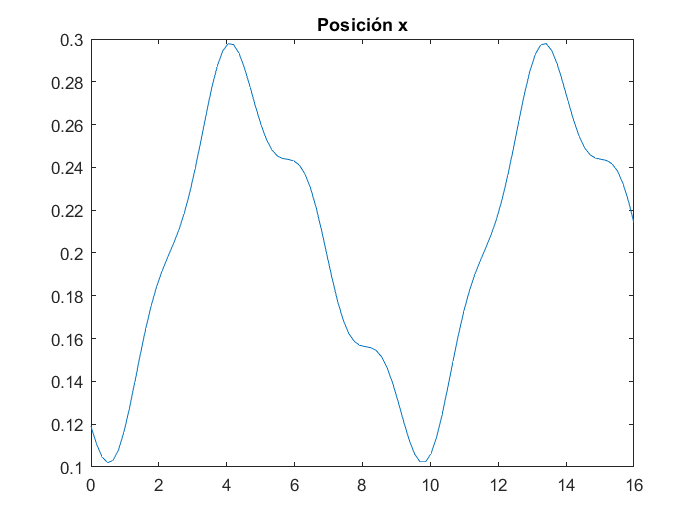

%Posición x
figure()
plot(t,eval(x))
title('Posición x')

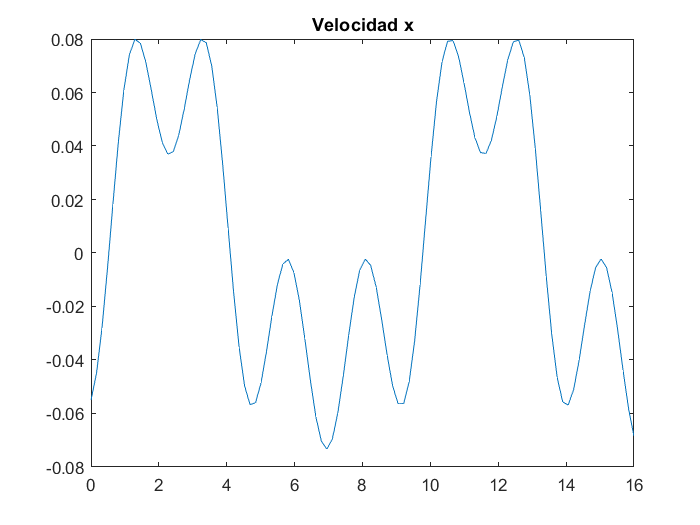

%Velocidad x
figure()
plot(t,eval(v_x))
title('Velocidad x')

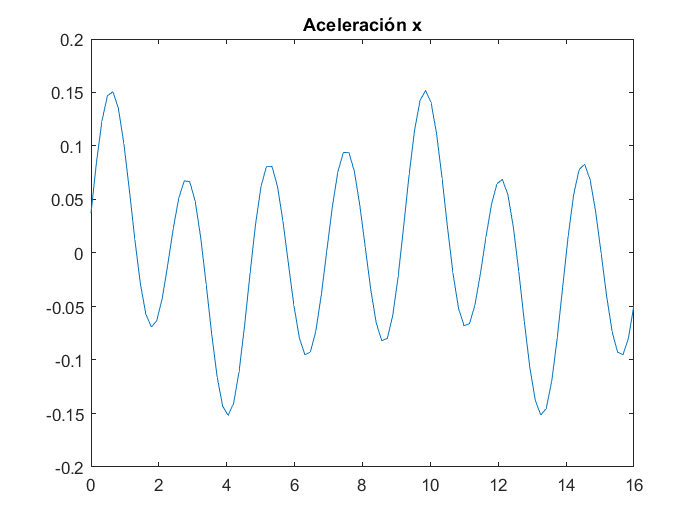

%Aceleración x
figure()
plot(t,eval(a_x))
title('Aceleración x')

## y

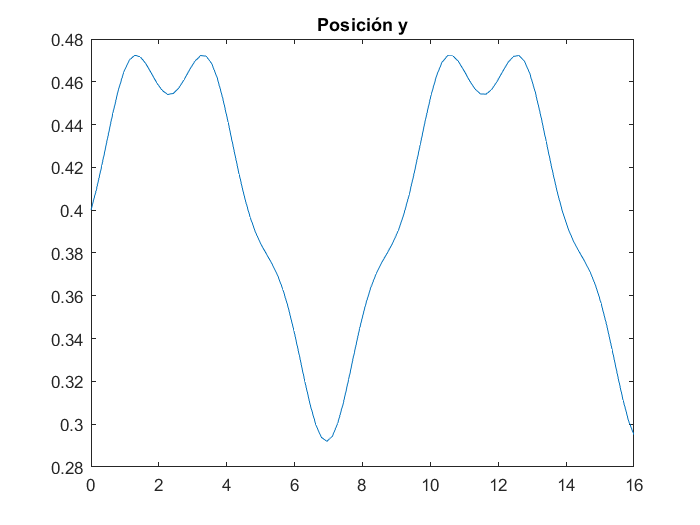

%Posición y
figure()
plot(t,eval(y))
title('Posición y')

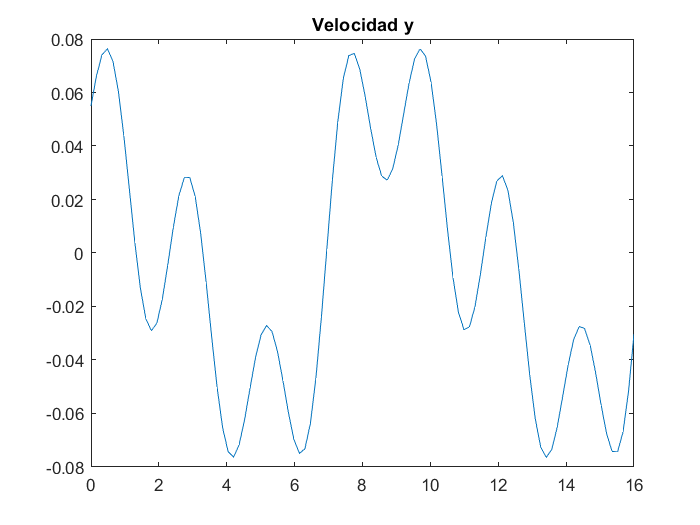

%Velocidad y
figure()
plot(t,eval(v_y))
title('Velocidad y')

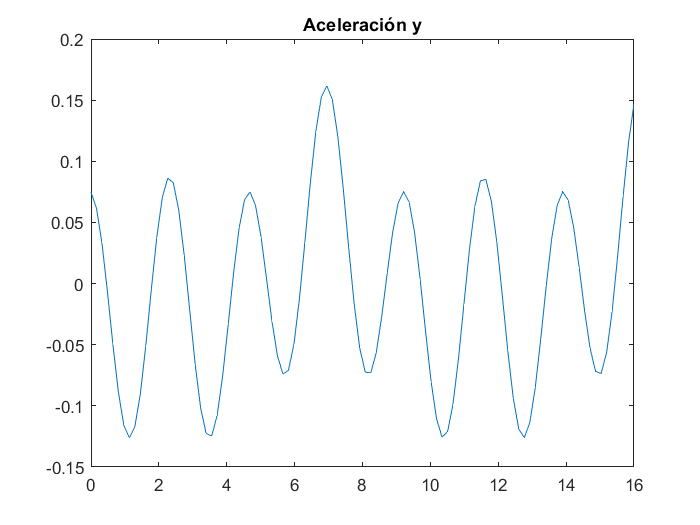

%Aceleración y
figure()
plot(t,eval(a_y))
title('Aceleración y')

## Motor 2

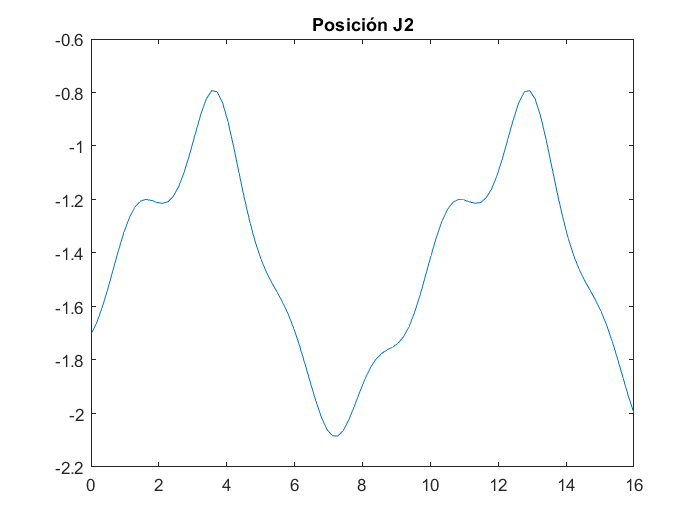

%Posición J2
figure()
plot(t,eval(theta_2))
title('Posición J2')

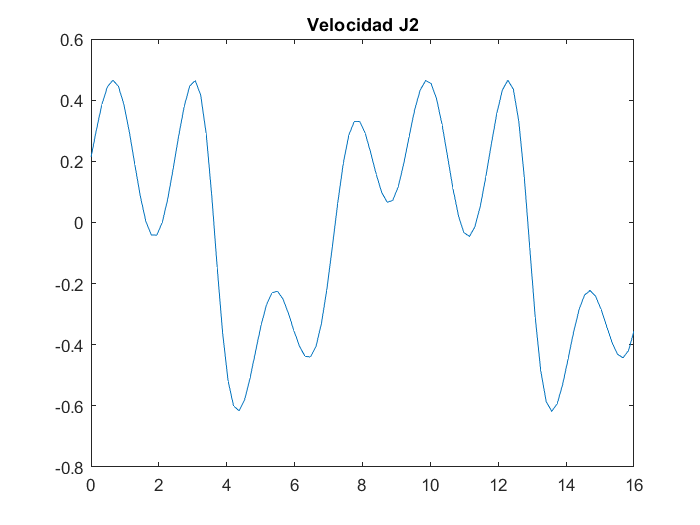

%Velocidad J2
figure()
plot(t,eval(omega_2))
title('Velocidad J2')

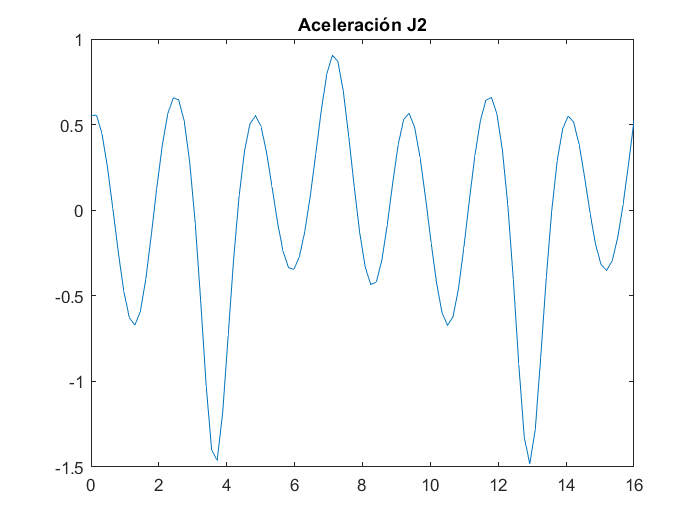

%Aceleración J2
figure()
plot(t,eval(alpha_2))
title('Aceleración J2')

## Motor 1

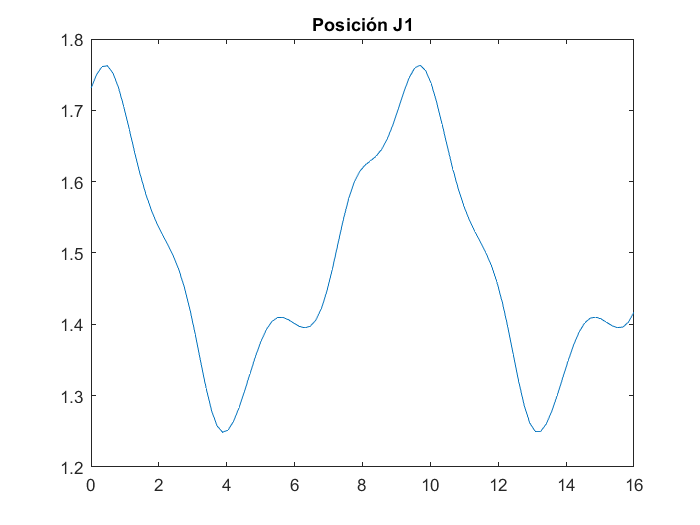

%Posición J1
figure()
plot(t,eval(theta_1))
title('Posición J1')

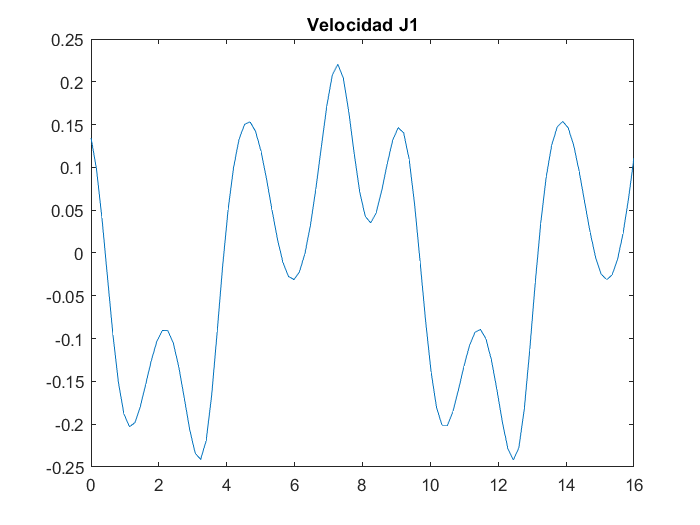

%Velocidad J1
figure()
plot(t,eval(omega_1))
title('Velocidad J1')

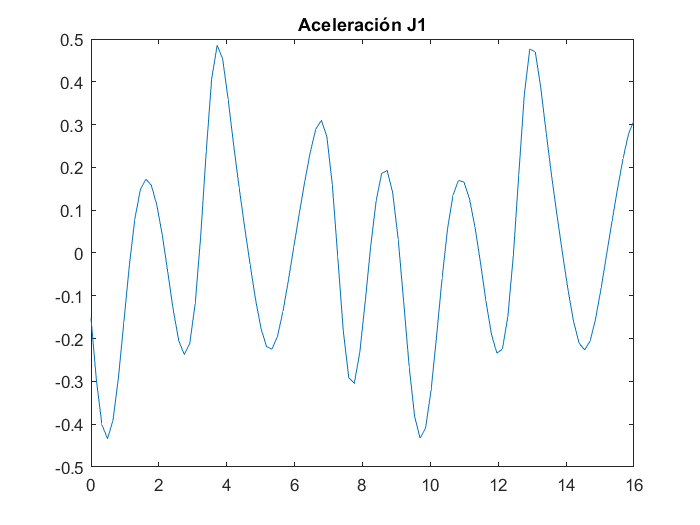

%Aceleración J1
figure()
plot(t,eval(alpha_1))
title('Aceleración J1')

## Posiciones angulares

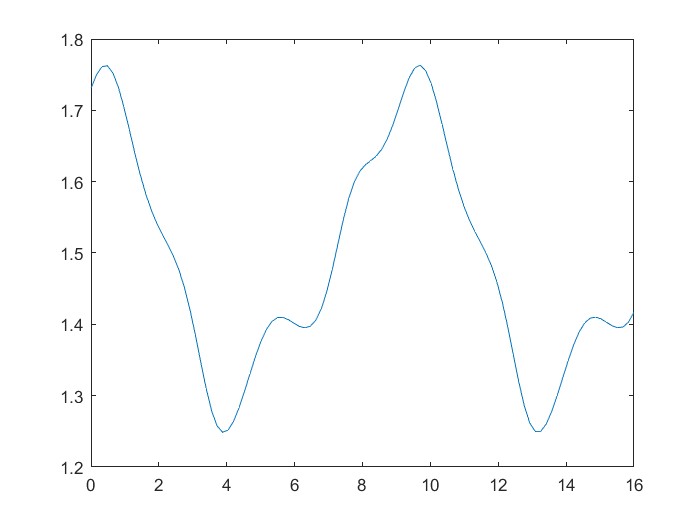

figure()
plot(t,eval(theta_1))

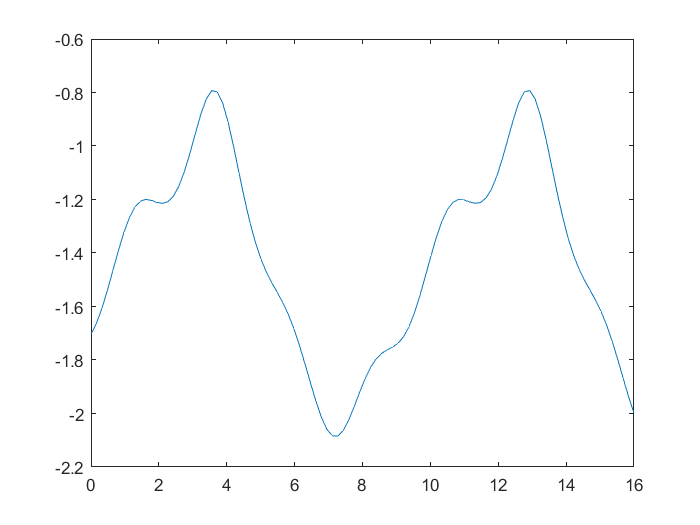


figure()
plot(t,eval(theta_2))

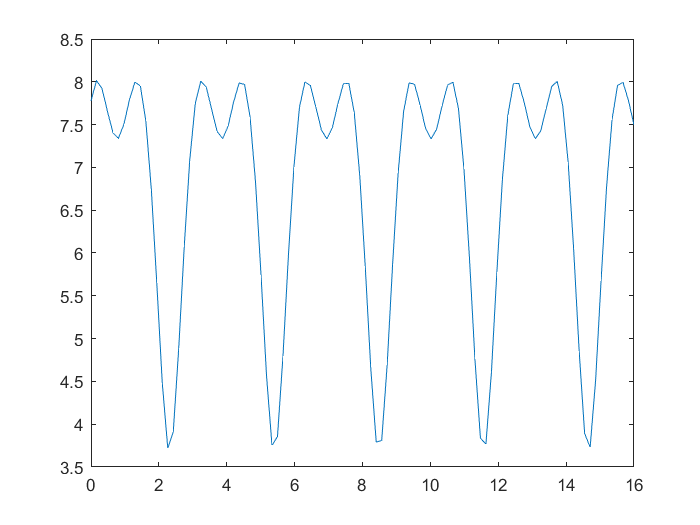


figure()
plot(t,eval(v)*100)

## Torques

## M2

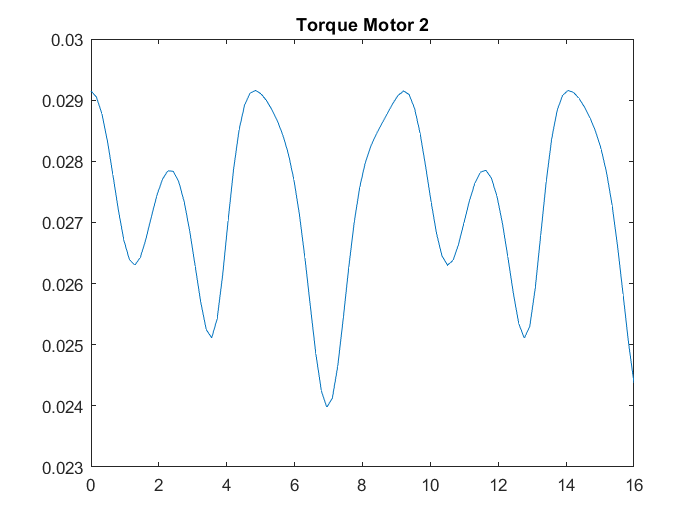

g=9.81;
m2=0.0323;
T_in2=(m2*(d2^2)*alpha_2)/3;
T_g2=(m2*g*d2*cos(theta_1+theta_2))/2;
T_m2=T_in2+T_g2;
figure()
plot(t,eval(T_m2))
title('Torque Motor 2')

## M1

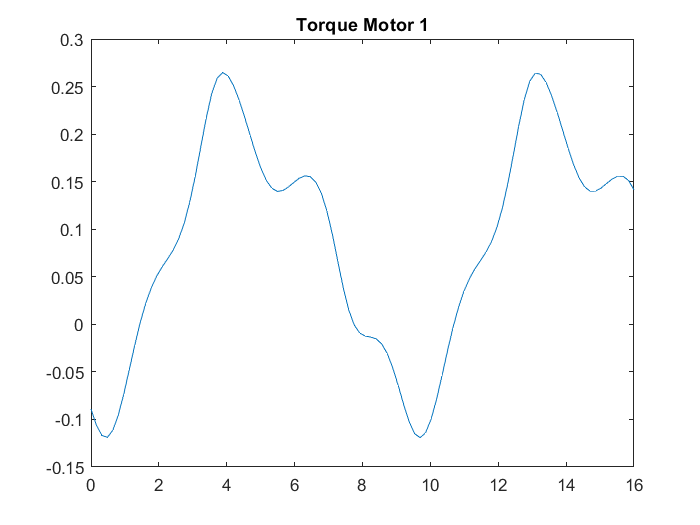

m1=0.04;
mm2=0.043;
mst2=0.0879;
Je1=m1*(d1^2)/3;
Jm2=mm2*(d1^2);
Jst2=mst2*(d1^2);
Je2=0;
J1=Je1+Jm2+Jst2+Je2;
T_in1=J1*alpha_1;
T_g1=g*(((d1*cos(theta_1))*((m1/2)+mm2+mst2+m2))+(m2*d2*cos(theta_1+theta_2)/2));
T_m1=T_in1+T_g1;
figure()
plot(t,eval(T_m1))
title('Torque Motor 1')